delta_th = th_true(1:1000) - x_kpost(1:1000,3);
delta_th = asin(sin(delta_th));
std_dev = sqrt(variances);

ylim1 = 25;

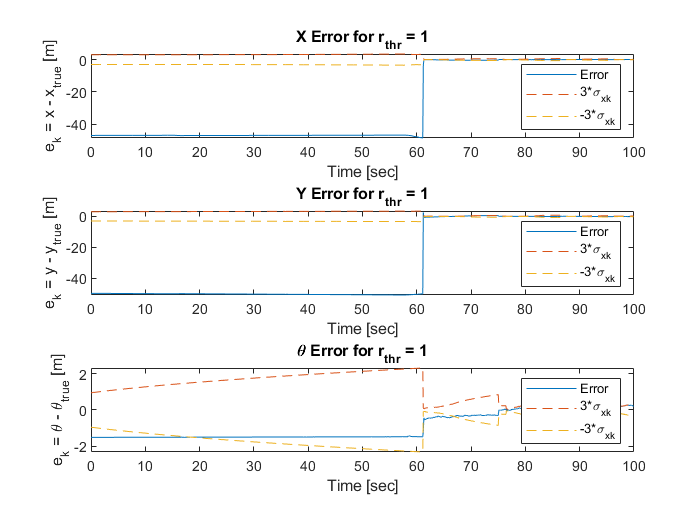

figure
%PLOT X_ERROR
subplot(3,1,1)
plot(t(1:1000,1), x_true(1:1000,1)-x_kpost(1:1000,1), t(1:1000,1), 3*std_dev(1,:),'--',t(1:1000,1),-3*std_dev(1,:),'--')
xlim([0,100])
%ylim([-ylim1,ylim1])
legend('Error','3*\sigma_{xk}','-3*\sigma_{xk}', 'Location','southeast')
title(['X Error for r_{thr} = ' ,num2str(r_thresh)],'FontSize',20)
xlabel('Time [sec]','FontSize',20)
ylabel('e_{k} = x - x_{true} [m]','FontSize',20)

subplot(3,1,2)
%PLOT Y_ERROR
plot(t(1:1000,1), y_true(1:1000,1)-x_kpost(1:1000,2), t(1:1000,1), 3*std_dev(2,:),'--',t(1:1000,1),-3*std_dev(2,:),'--')
xlim([0,100])
%ylim([-ylim1,ylim1])
legend('Error','3*\sigma_{xk}','-3*\sigma_{xk}', 'Location','southeast')
title(['Y Error for r_{thr} = ' ,num2str(r_thresh)],'FontSize',20)
xlabel('Time [sec]','FontSize',20)
ylabel('e_{k} = y - y_{true} [m]','FontSize',20)

subplot(3,1,3)
%PLOT Y_ERROR
plot(t(1:1000,1), delta_th, t(1:1000,1), 3*std_dev(3,:),'--',t(1:1000,1),-3*std_dev(3,:),'--')
xlim([0,100])
%ylim([-1,1])
legend('Error','3*\sigma_{xk}','-3*\sigma_{xk}', 'Location','southeast')
title(['\theta Error for r_{thr} = ' ,num2str(r_thresh)],'FontSize',20)
xlabel('Time [sec]','FontSize',20)
ylabel('e_{k} = \theta - \theta_{true} [m]','FontSize',20)